# Mobile Robot Short project support

Use this preliminary code as the basis to develop the comming Short Project

## Pose stimation code

Open: EKF_Pose_estimation.slx model.

See: Where2Find_Code.pdf file to learn how to acces to Pose_ estimation code and plotting results.

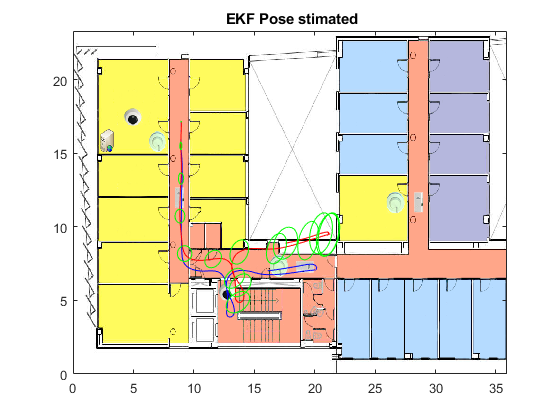

ProcNoiseTheta = 9.0000e-06

Ts = 0.0200

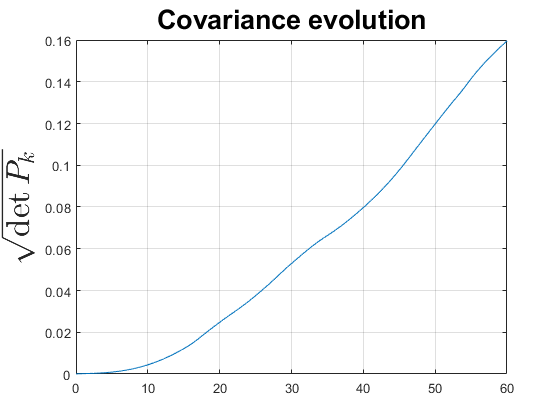

clear
close all
clf
sim("EKF_Pose_estimation_1.slx" )

## Plotting the enviroment and estimated trajectory

Attention "Do not change proces noise"  in the Simulink model: EKF_Pose_estimation_1.slx.

Laser_Data_CV_d_b were computed with: 

ProcNoiseD=0.019^2; and ProcNoiseTheta=0.003^2

figure1=figure

figure1 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


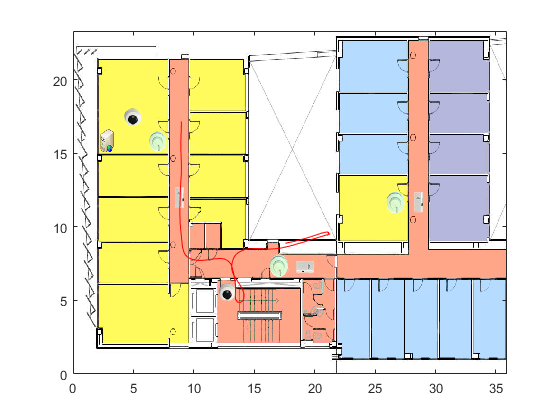

I=imread('Enviroment.png');
x_ima=[0 35.9];
y_ima=[23.31 0];
image(I,'XData',x_ima,'YData',y_ima);
axis xy
hold on
plot(Pose_est.Data(:,1),Pose_est.Data(:,2),'r')

## Land Marks

They are known. They can be extracter from laser data, there are easy algorithms for finding they, like corner detection, etc ...

Lmk= [7.934 16.431 0 1;...
      9.583 16.431 0 1;...
      9.584 13.444 0 1;...
      9.584 10.461 0 1;...
      7.973 10.534 0 1;...
      7.934  7.547 0 1;...
      9.584  6.654 0 1;...
     13.001  6.525 0 1;...
     17.007  8.136 0 1];

### Plot Land Marks 

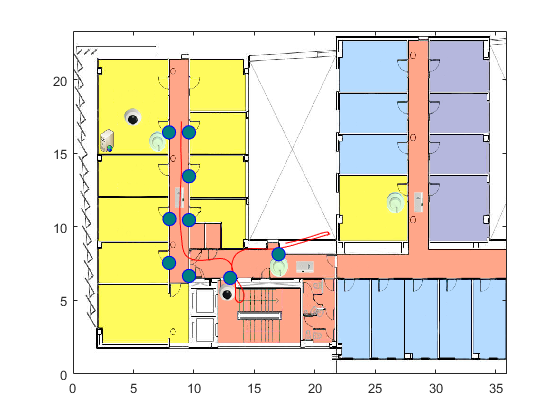

hold on
sz = 100;
s=scatter(Lmk(:,1),Lmk(:,2),sz);
s.LineWidth = 0.6;
s.MarkerEdgeColor = 'b';
s.MarkerFaceColor = [0 0.5 0.5];

## See an animation

In our system the computer is able to detect the landMark every 400ms

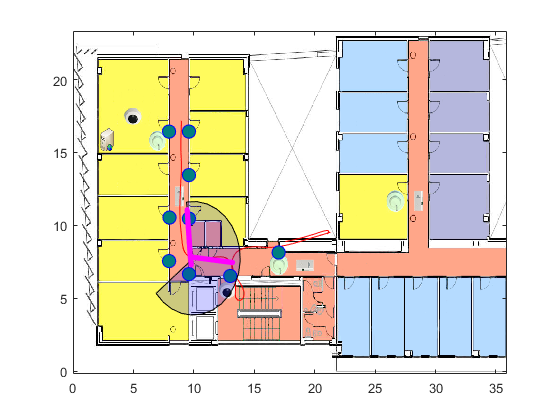

load('Laser_Data_CV__d_b.mat') % See the data
%%%%%%%%%%%%Robot shape %%%%%%%%%%%%
Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]';% The Robot icon is a triangle
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%Laser foot print %%%%%%%%
Laser_Range=3.9;% meters
w=linspace(-30*pi/180,210*pi/180,20); %Laser foot print
s_x=Laser_Range*sin(w);s_y=Laser_Range*cos(w);
Lfp.v=[[s_x 0];[s_y 0]]';
Lfp.f= [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 1];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hold on
axis([0 35.9 0 23.31]);
Robot_tr=eye(4)*Robot;
hr=patch(Robot_tr(1,1), Robot_tr(2,1),'b');
hlfp=patch('Faces',Lfp.f,'Vertices',Lfp.v,'FaceColor','blue','FaceAlpha',.2);
hll=line([0 0.01],[0 0.01],'Color','red','LineStyle','-');
hr=[];
hlft=[];
hll=[];
sz = 100; % to see thing biger
speed=5; % to speed up the animation
for i=1:860 % Use the for loop to see a movie
    k_m=mod(i,speed);
    
        delete (hr); % Deleting figures and laser lines
        delete (hlfp);
        delete (hll)
        s=scatter(Lmk(:,1),Lmk(:,2),sz);
        s.LineWidth = 0.6;
        s.MarkerEdgeColor = 'b';
        s.MarkerFaceColor = [0 0.5 0.5];
        Robot_pose=transl(Pose_est.Data(i,1),Pose_est.Data(i,2),0)*trotz(Pose_est.Data(i,3));
        Robot_tr=Robot_pose*Robot;% moving the robot 
        Laser_fp=Robot_pose*transl(0.25,0,0)*[Lfp.v zeros(21,1) ones(21,1)]';
        axis([0 35.9 0 23.31]);
        hr=patch(Robot_tr(1,:), Robot_tr(2,:),'b');
        hlfp=patch('Faces',Lfp.f,'Vertices',Laser_fp(1:2,:)','FaceColor','blue','FaceAlpha',.2);
        Ls_lm_W=Robot_pose*[l_s_d(i,:).*cos(l_s_b(i,:));l_s_d(i,:).*sin(l_s_b(i,:)) ;zeros(1,9) ;ones(1,9)];
        position=transl(Robot_pose);
        hll=line([position(1) Ls_lm_W(1,1)...X's
                  position(1) Ls_lm_W(1,2)...
                  position(1) Ls_lm_W(1,3)...
                  position(1) Ls_lm_W(1,4)...
                  position(1) Ls_lm_W(1,5)...
                  position(1) Ls_lm_W(1,6)...
                  position(1) Ls_lm_W(1,7)...
                  position(1) Ls_lm_W(1,8)...
                  position(1) Ls_lm_W(1,9)],...
                 [position(2) Ls_lm_W(2,1)...%Y's
                  position(2) Ls_lm_W(2,2)...
                  position(2) Ls_lm_W(2,3)...
                  position(2) Ls_lm_W(2,4)...
                  position(2) Ls_lm_W(2,5)...
                  position(2) Ls_lm_W(2,6)...
                  position(2) Ls_lm_W(2,7)...
                  position(2) Ls_lm_W(2,8)...
                  position(2) Ls_lm_W(2,9)],'Color','m','LineStyle','-', 'LineWidth', 4);
        
        pause(0.01);
end

## Testing Similarity Transform

Show up again the Enriroment with both trajectories: 

Theoric - Pose_t and estimate Pose_est

figure1=figure

figure1 =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


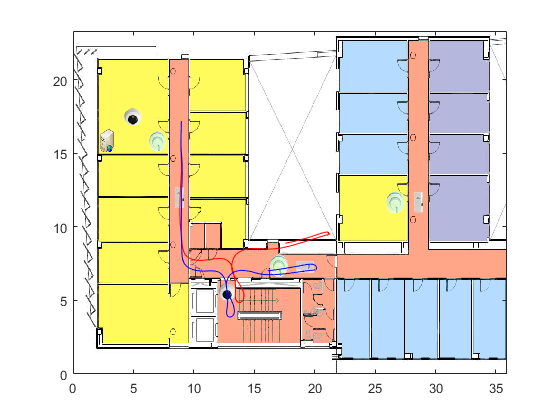

I=imread('Enviroment.png');
x_ima=[0 35.9];
y_ima=[23.31 0];
image(I,'XData',x_ima,'YData',y_ima);
axis xy
hold on
plot(Pose_est.Data(:,1),Pose_est.Data(:,2),'r')
plot(Pose_t.Data(:,1),Pose_t.Data(:,2),'b')

## Analize simulation 

at time array index 860, i.e t=860*0.02=17.2 seg. and see the differences

m=860

m = 860

Robot_pose=transl(Pose_est.Data(m,1),Pose_est.Data(m,2),0)*trotz(Pose_est.Data(m,3))

Robot_pose =     0.9281    0.3722         0    9.6984
   -0.3722    0.9281         0    7.8317
         0         0    1.0000         0
         0         0         0    1.0000


Robot_m=transl(Robot_pose)

Robot_m =     9.6984
    7.8317
         0


Robot_pose_teo=transl(transl(Pose_t.Data(m,1),Pose_t.Data(m,2),0)*trotz(Pose_t.Data(m,3)))

Robot_pose_teo =     9.5581
    7.2179
         0


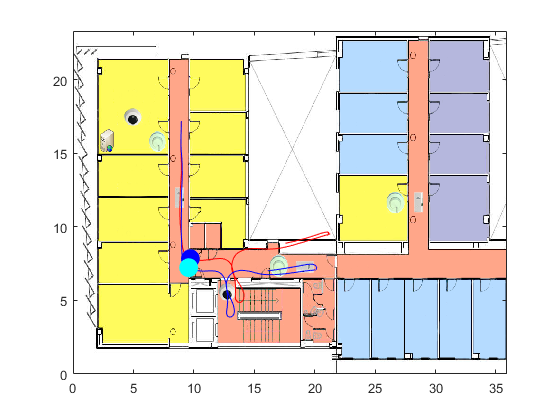

scatter(Robot_m(1),Robot_m(2),200, 'b','filled');
scatter(Robot_pose_teo(1),Robot_pose_teo(2),200, 'c','filled');

## Read the laser

d_4=l_s_d(m,4)

d_4 = 3.2481

b_4=l_s_b(m,4)

b_4 = 2.0338

d_78=l_s_d(m,7:8)

d_78 =     0.5699    3.5156


b_78=l_s_b(m,7:8)

b_78 =     5.2291    0.2723


## Laser 2 Word

[x4,y4]=pol2cart(b_4(1,1),d_4(1,1))

x4 = -1.4507

y4 = 2.9061

[x7,y7]=pol2cart(b_78(1,1),d_78(1,1))

x7 = 0.2815

y7 = -0.4955

[x8,y8]=pol2cart(b_78(1,2),d_78(1,2))

x8 = 3.3860

y8 = 0.9455


L_m4_w=Robot_pose*[x4 y4 0 1]'

L_m4_w =     9.4337
   11.0689
         0
    1.0000


L_m7_w=Robot_pose*[x7 y7 0 1]'

L_m7_w =     9.7753
    7.2670
         0
    1.0000


L_m8_w=Robot_pose*[x8 y8 0 1]'

L_m8_w =    13.1931
    7.4488
         0
    1.0000


Innovation=[L_m4_w L_m7_w L_m8_w];

## LandMark needed

LandMark= Lmk'

LandMark =     7.9340    9.5830    9.5840    9.5840    7.9730    7.9340    9.5840   13.0010   17.0070
   16.4310   16.4310   13.4440   10.4610   10.5340    7.5470    6.6540    6.5250    8.1360
         0         0         0         0         0         0         0         0         0
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


LandMark= [LandMark(1:2,4) LandMark(1:2,7:8)]

LandMark =     9.5840    9.5840   13.0010
   10.4610    6.6540    6.5250


## Plot the scene

Legend for points:

Blue: Estimated Pose

Cyan: True/theoric Pose

Red: known Land Marks

Green: Measured Land Marks

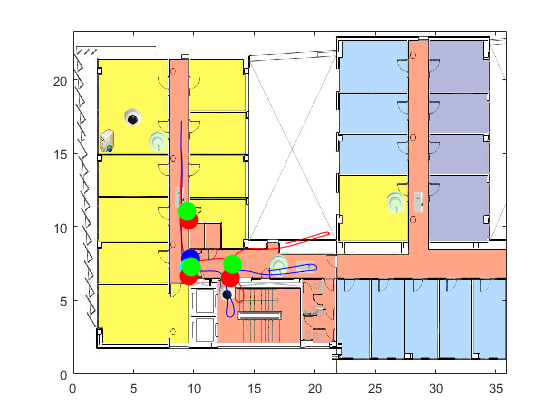

scatter(LandMark(1,:),LandMark(2,:),200, 'r','filled');
scatter(L_m4_w(1),L_m4_w(2),200, 'g','filled');
scatter(L_m7_w(1),L_m7_w(2),200, 'g','filled');
scatter(L_m8_w(1),L_m8_w(2),200, 'g','filled');

## Building the Matrices A & B

A = []; 
for i=1:size(LandMark, 2)
    A = [A;[LandMark(1,i),LandMark(2,i),1,0]];
    A = [A;[LandMark(2,i),-LandMark(1,i),0,1]]
end

A =     9.5840   10.4610    1.0000         0
   10.4610   -9.5840         0    1.0000


A =     9.5840   10.4610    1.0000         0
   10.4610   -9.5840         0    1.0000
    9.5840    6.6540    1.0000         0
    6.6540   -9.5840         0    1.0000


A =     9.5840   10.4610    1.0000         0
   10.4610   -9.5840         0    1.0000
    9.5840    6.6540    1.0000         0
    6.6540   -9.5840         0    1.0000
   13.0010    6.5250    1.0000         0
    6.5250  -13.0010         0    1.0000


B = [];
for i=1:size(Innovation, 2)
    B = [B; Innovation(1,i); Innovation(2,i)]
end

B =     9.4337
   11.0689


B =     9.4337
   11.0689
    9.7753
    7.2670


B =     9.4337
   11.0689
    9.7753
    7.2670
   13.1931
    7.4488


## Finding the error in pose

X = inv((A'*A))*A'*B;
tx_ST = X(3)

tx_ST = 0.8113

ty_ST = X(4)

ty_ST = -0.2284

alpha_ST = atan2(X(2),X(1))

alpha_ST = -0.0897

## Testing Least squared

A*[cos(alpha_ST) sin(alpha_ST) tx_ST ty_ST]'

ans =     9.4191
   11.0494
    9.7603
    7.2578
   13.1751
    7.4355


B

B =     9.4337
   11.0689
    9.7753
    7.2670
   13.1931
    7.4488


Innovation

Innovation =     9.4337    9.7753   13.1931
   11.0689    7.2670    7.4488
         0         0         0
    1.0000    1.0000    1.0000


## Testing at origen

Operation=trotz(-alpha_ST)*transl(tx_ST,ty_ST,0)*[LandMark; 0 0 0; 1 1 1]

Operation =     9.4363    9.7775   13.1923
   11.1231    7.3314    7.5092
         0         0         0
    1.0000    1.0000    1.0000


Innovation

Innovation =     9.4337    9.7753   13.1931
   11.0689    7.2670    7.4488
         0         0         0
    1.0000    1.0000    1.0000


## Going Back

Operation_back=transl(-tx_ST,-ty_ST,0)*trotz(alpha_ST)*Innovation

Operation_back =     9.5765    9.5760   12.9963
   10.4073    6.5901    6.4648
         0         0         0
    1.0000    1.0000    1.0000


LandMark

LandMark =     9.5840    9.5840   13.0010
   10.4610    6.6540    6.5250


## Cancel errors

Robot_error= transl(-tx_ST,-ty_ST,0)*trotz(alpha_ST)*[Robot_m;1]

Robot_error =     9.5500
    7.1593
         0
    1.0000


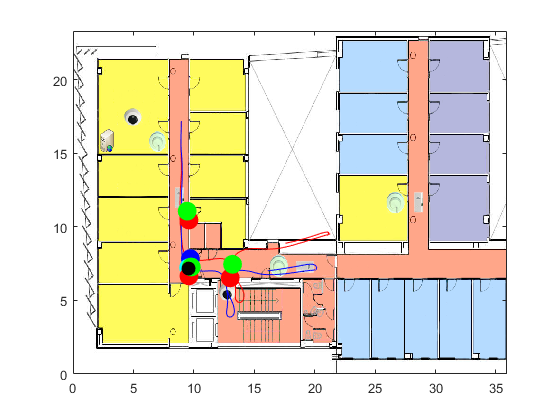

scatter(Robot_error(1),Robot_error(2),110, 'black','filled');